paramNameValStruct.SimulationMode = 'accelerator';
% paramNameValStruct.TimeOut        = 40;
simOut = sim('exp4M_CSVposRef',paramNameValStruct);
simOut.getSimulationMetadata.TimingInfo

ans = struct with fields:
          WallClockTimestampStart: '2022-02-18 10:08:34'
           WallClockTimestampStop: '2022-02-18 10:10:07'
    InitializationElapsedWallTime: 2.5319
         ExecutionElapsedWallTime: 89.5887
       TerminationElapsedWallTime: 1.6227
             TotalElapsedWallTime: 93.7432
                     ProfilerData: 'Profiler is not enabled'


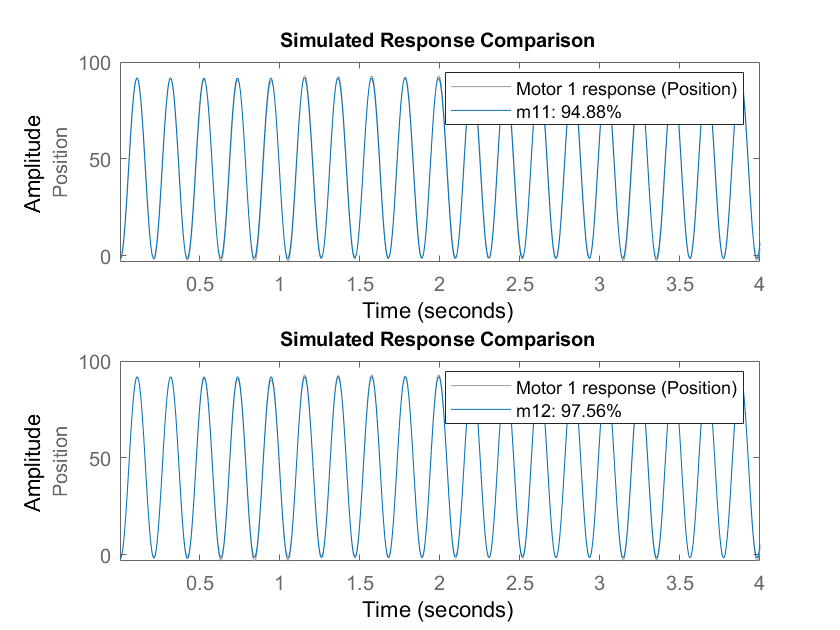

p1 = simOut.p1;
Ts = simOut.tout(2);
% create iddata type with inputs and outputs
data1 = iddata(p1.Data(:,2),p1.Data(:,1),Ts,'Name','Motor 1 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 1 pole and no zero
m11 = tfest(data1,1,0); % m11.Report.Fit
% transfer function estimation with 2 poles and no zero
m12 = tfest(data1,2,0); % m12.Report.Fit
figure
subplot(2,1,1)
compare(data1,m11) % first order model evaluation
subplot(2,1,2)
compare(data1,m12) % second order model evaluation

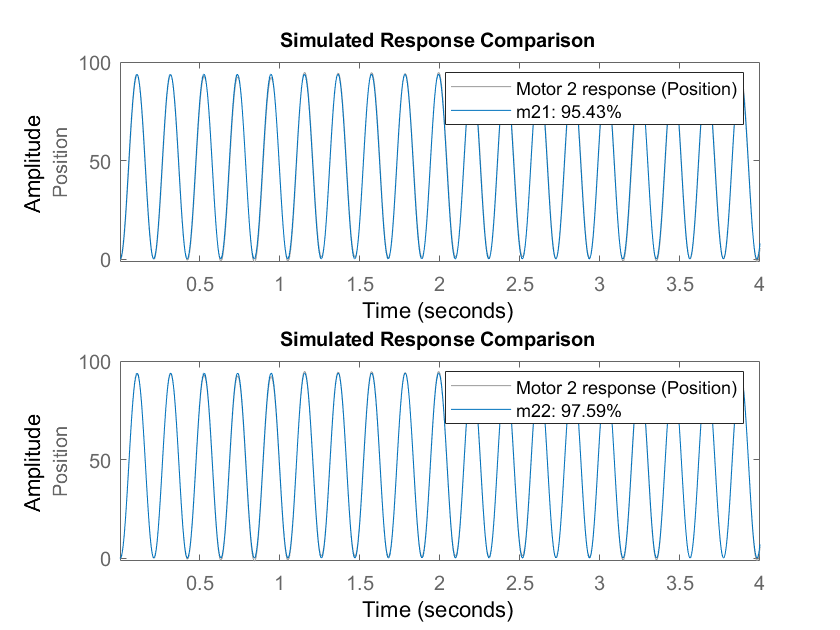

p2 = simOut.p2;
data2 = iddata(p2.Data(:,2),p2.Data(:,1),Ts,'Name','Motor 2 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 1 pole and no zero
m21 = tfest(data2,1,0);
% transfer function estimation with 2 poles and no zero
m22 = tfest(data2,2,0);
figure
subplot(2,1,1)
compare(data2,m21) % first order model evaluation
subplot(2,1,2)
compare(data2,m22) % second order model evaluation

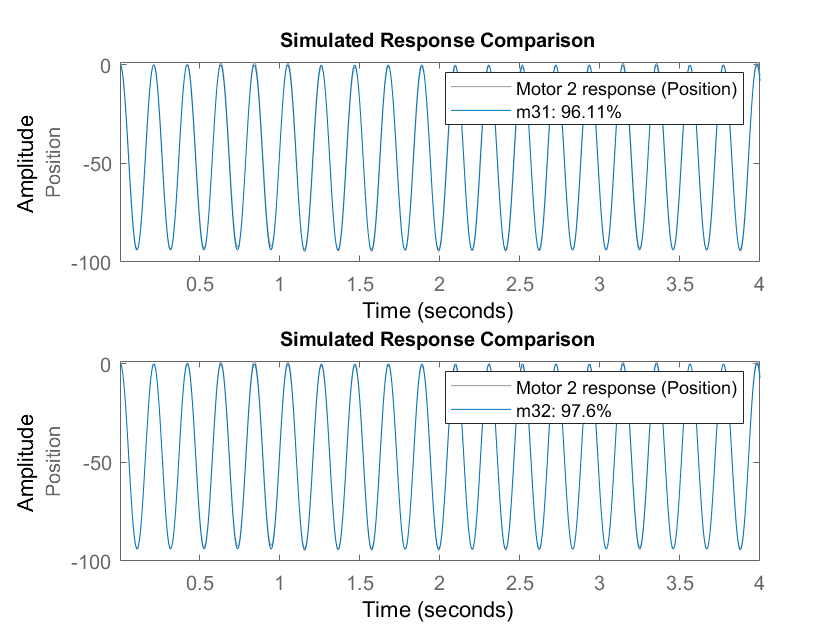

p3 = simOut.p3;
data3 = iddata(p3.Data(:,2),p3.Data(:,1),Ts,'Name','Motor 2 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 1 pole and no zero
m31 = tfest(data3,1,0);
% transfer function estimation with 2 poles and no zero
m32 = tfest(data3,2,0);
figure
subplot(2,1,1)
compare(data3,m31) % first order model evaluation
subplot(2,1,2)
compare(data3,m32) % second order model evaluation

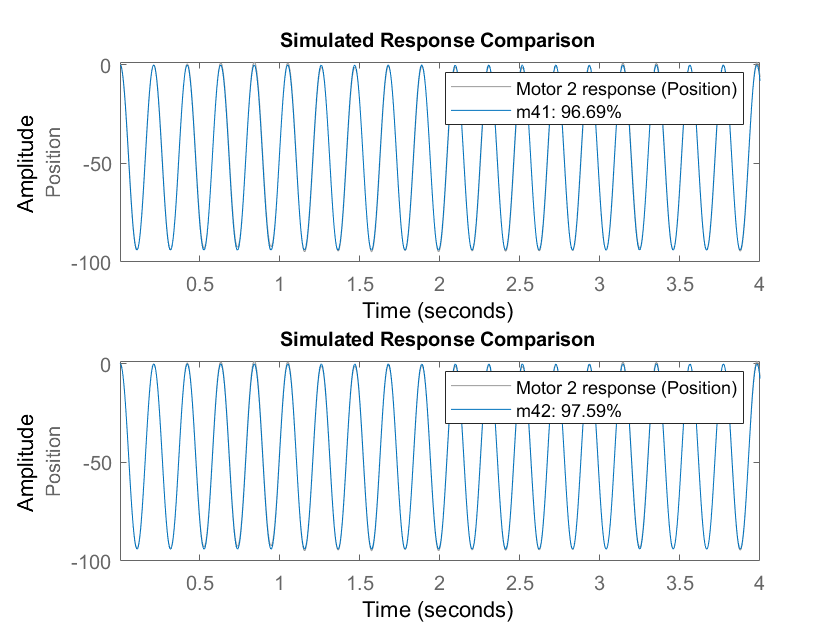

p4 = simOut.p4;
data4 = iddata(p4.Data(:,2),p4.Data(:,1),Ts,'Name','Motor 2 response', ...
    'InputName',{'Time'},'InputUnit',{'s'}, ...
    'OutputName',{'Position'},'OutputUnit',{'rad'});
% transfer function estimation with 1 pole and no zero
m41 = tfest(data4,1,0);
% transfer function estimation with 2 poles and no zero
m42 = tfest(data4,2,0);
figure
subplot(2,1,1)
compare(data4,m41) % first order model evaluation
subplot(2,1,2)
compare(data4,m42) % second order model evaluation

From the results above, the first order transfer function model has better performance compared to second order variation. The first order transfer functions also reduce computation complexity. Thus it provides faster response.

save Data/Exoskeleton/motor4Model m11 m21 m31 m41 p1 p2 p3 p4 m12 m22 m32 m42 Ts
clear data1 data2 data3 data4 opts tabularData
model = 'tf4M_CSVposRef_ctrlDesign';
load_system(model)
setActiveConfigSet(model, 'systemIdentification');
save_system(model)
open(model)